load_data

task1_1(Xtrn, Ytrn);

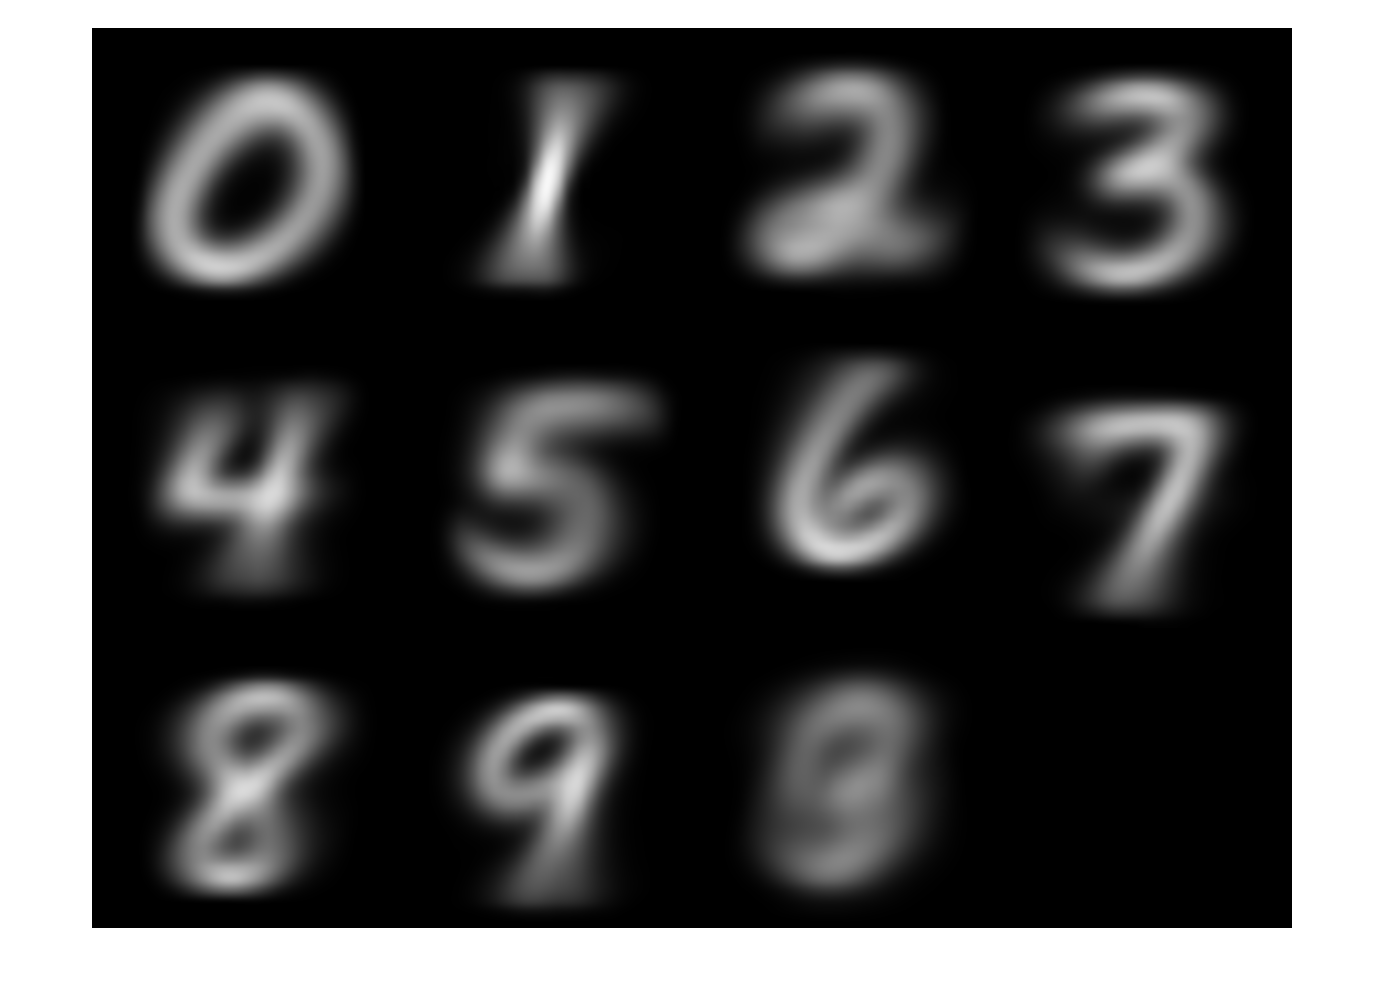

M = task1_2(Xtrn, Ytrn);

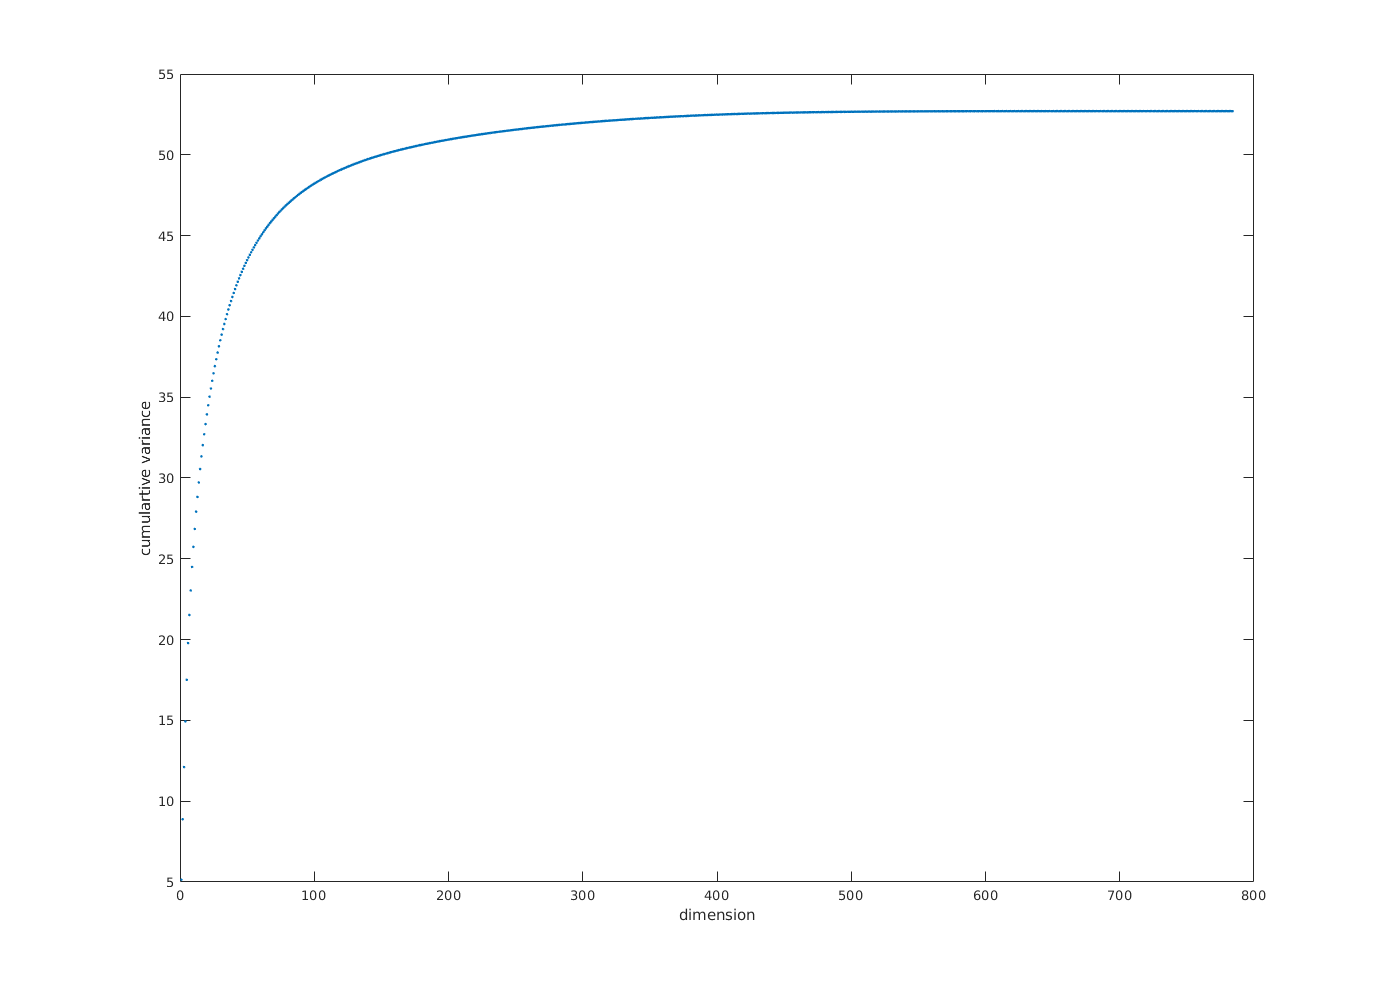

[EVecs, EVals, CumVar, MinDims] = task1_3(Xtrn);

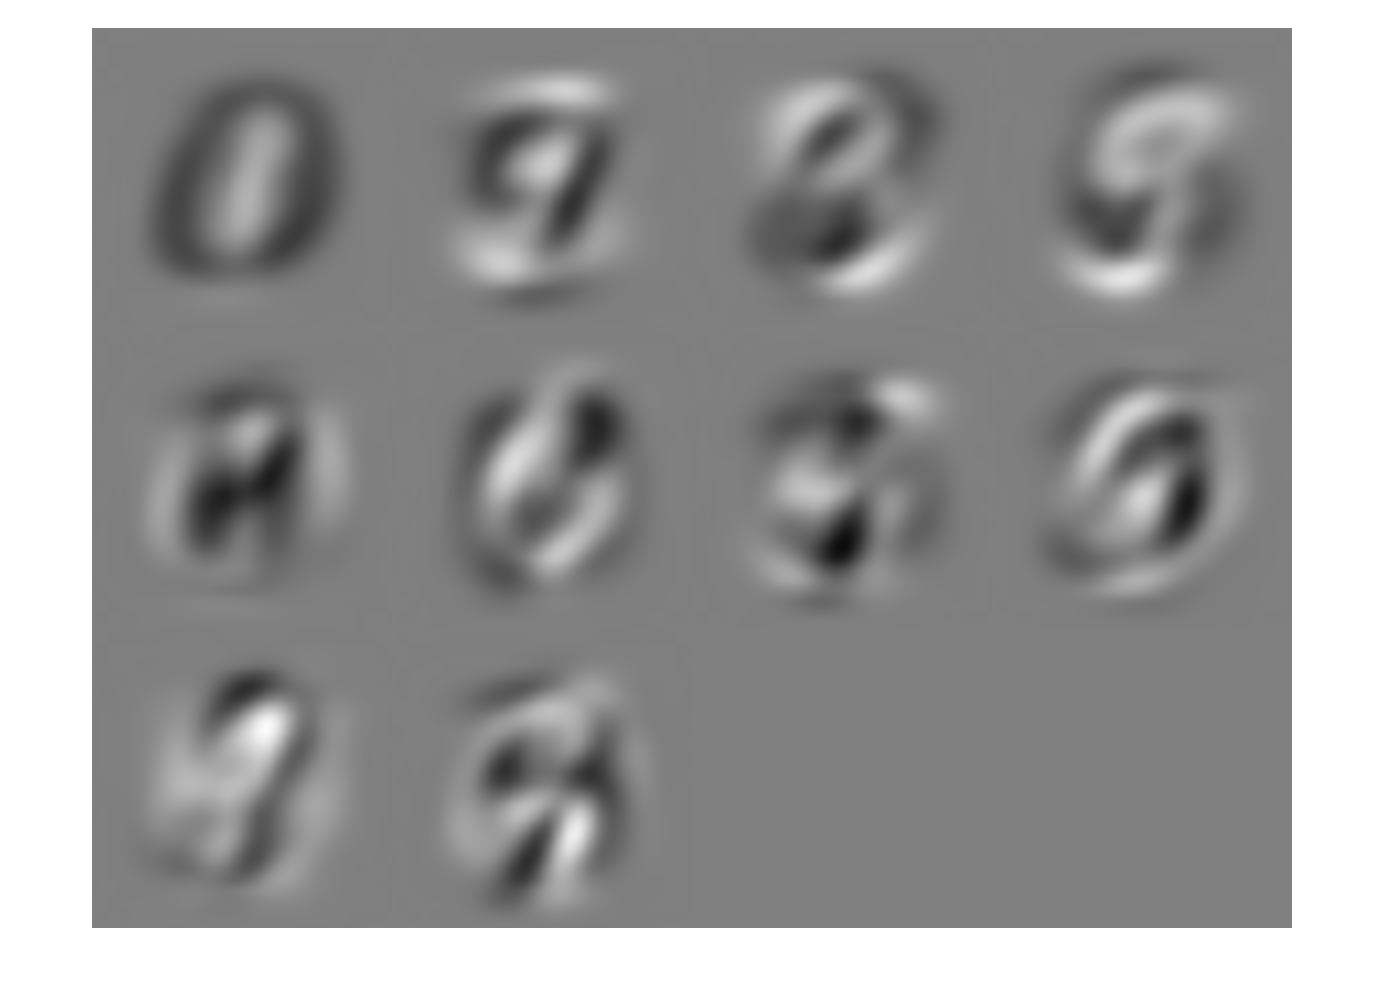

load('task1_3_evecs.mat', 'EVecs');
task1_4(EVecs);

k = 5

Elapsed time is 6.477356 seconds.


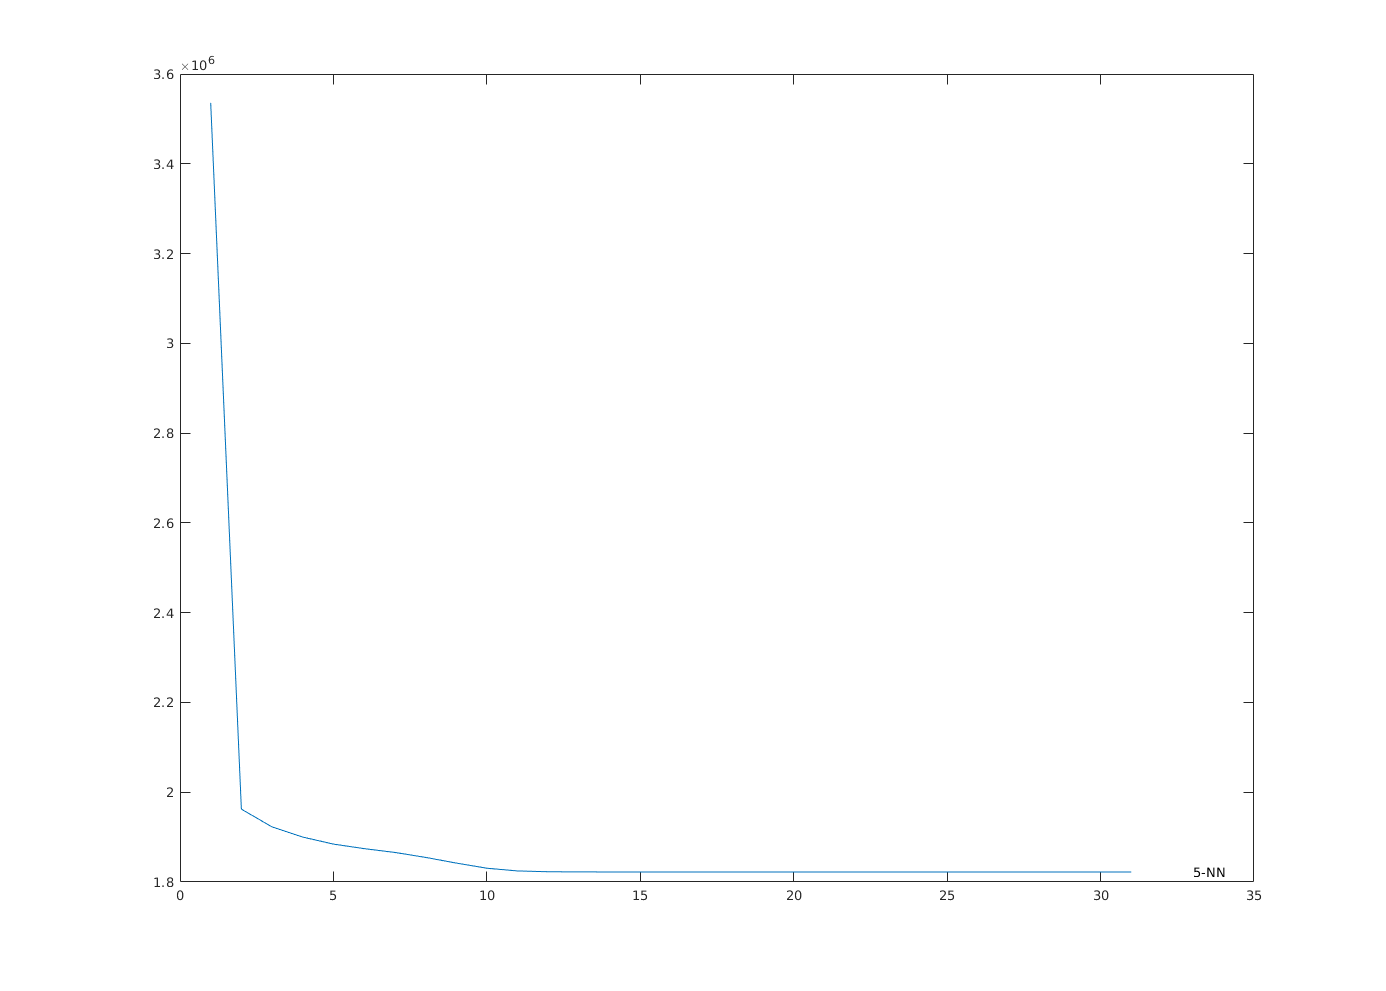

Ks = [5];
task1_5(Xtrn, Ks);

k = 1

SSE = 	1.0e+06 *

    4.3546
    2.2136


Elapsed time is 1.814584 seconds.


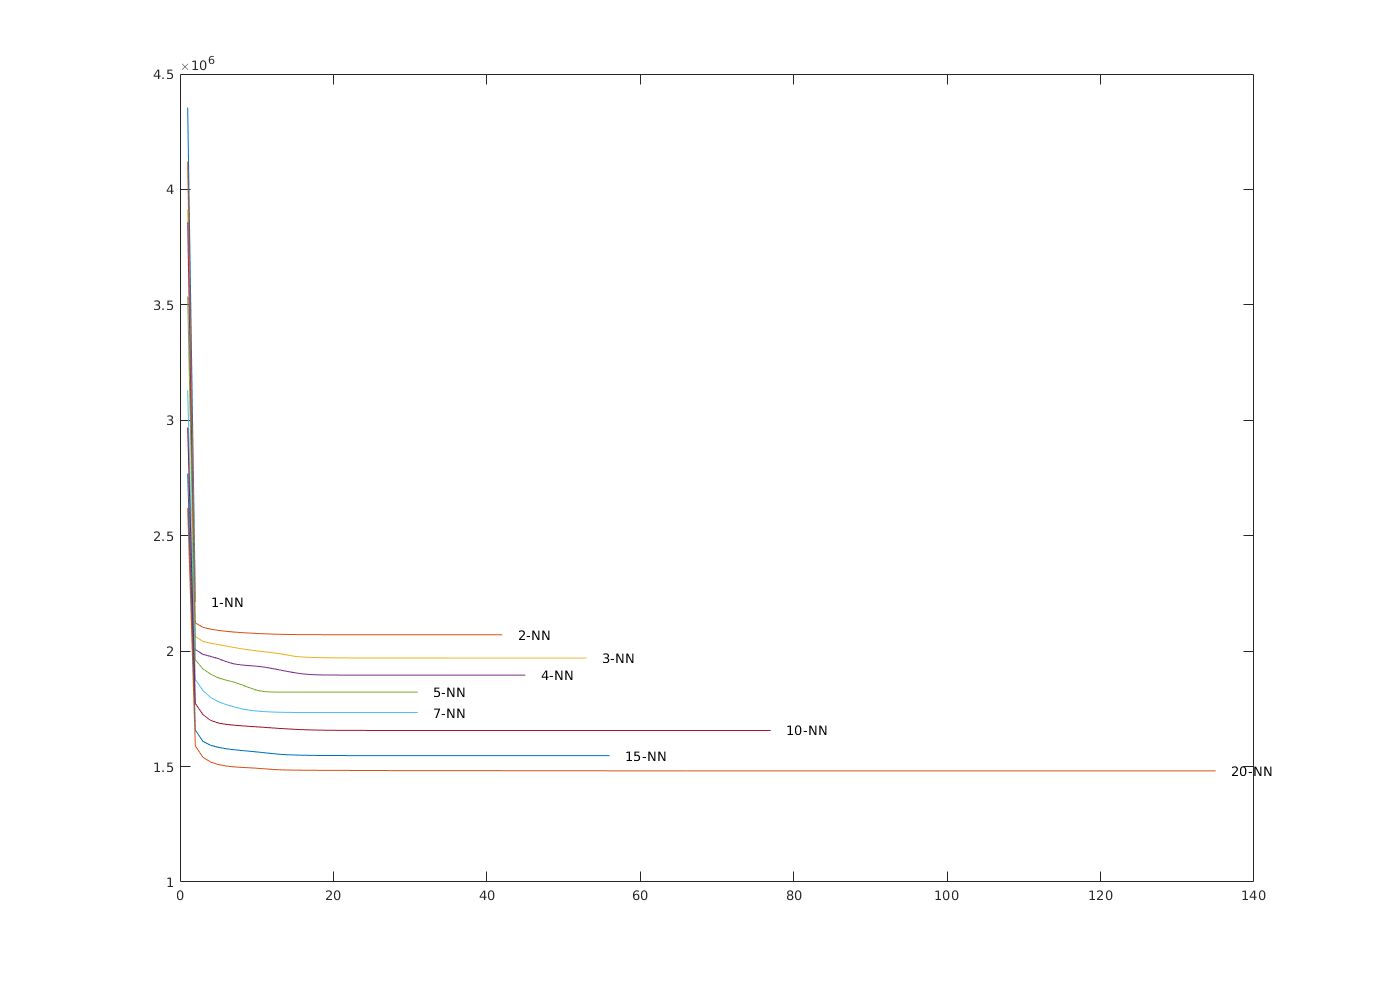

k = 2

Elapsed time is 11.165499 seconds.


k = 3

Elapsed time is 14.870988 seconds.


k = 4

Elapsed time is 13.365859 seconds.


k = 5

Elapsed time is 9.480774 seconds.


k = 7

Elapsed time is 10.341018 seconds.


k = 10

Elapsed time is 24.097241 seconds.


k = 15

Elapsed time is 18.974546 seconds.


k = 20

Elapsed time is 49.994306 seconds.


Ks = [1,2,3,4,5,7,10,15,20];
task1_5(Xtrn, Ks);

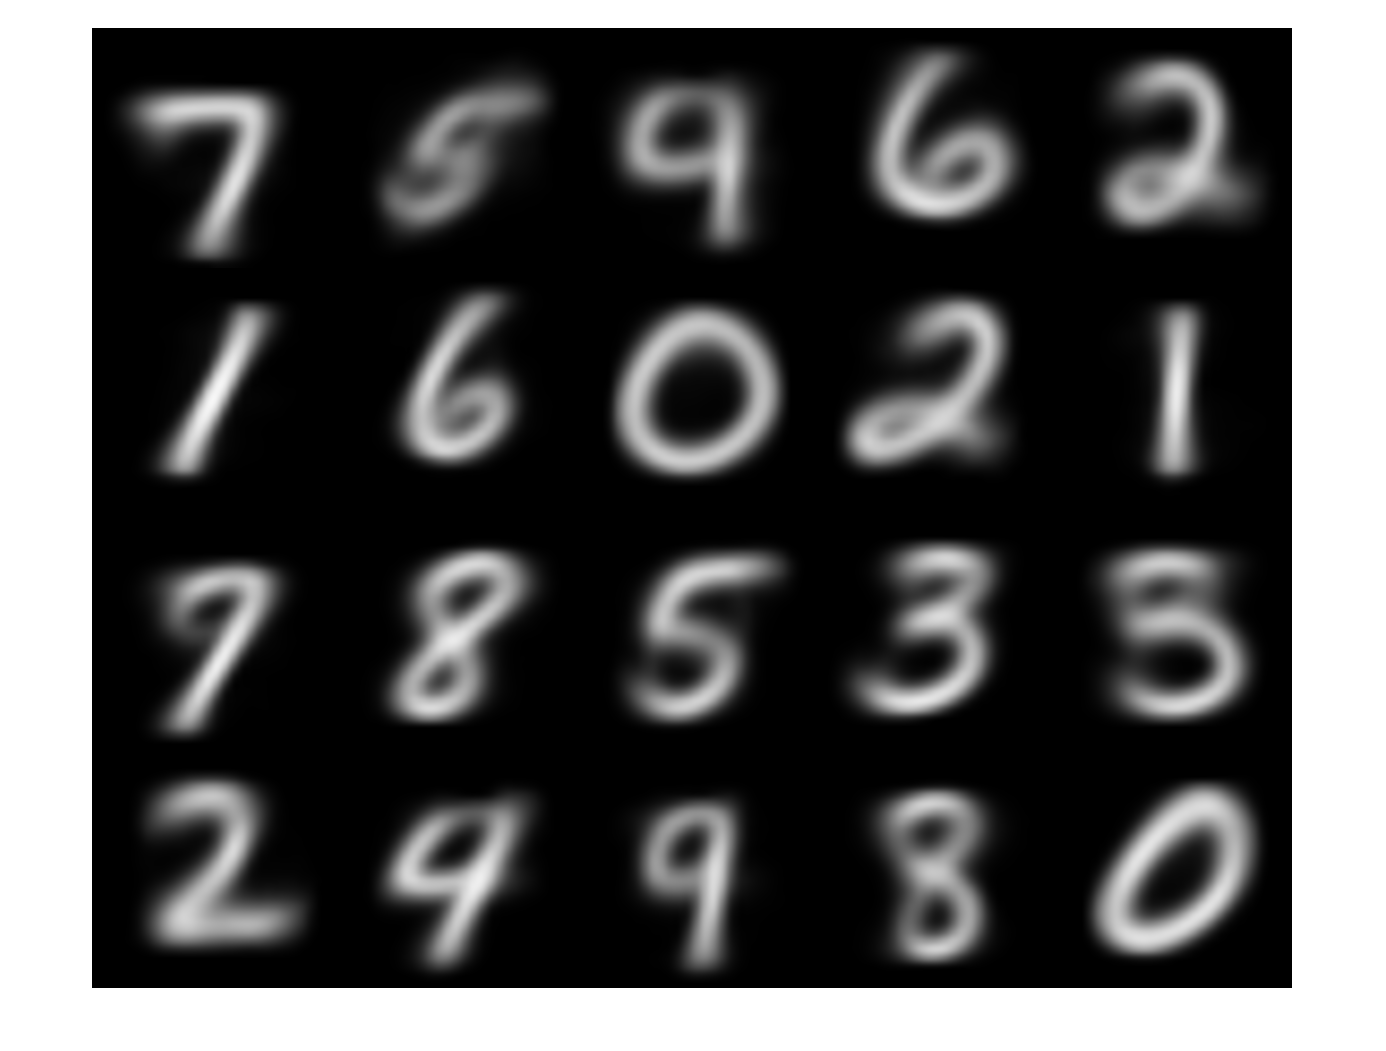

ans =            1       40000


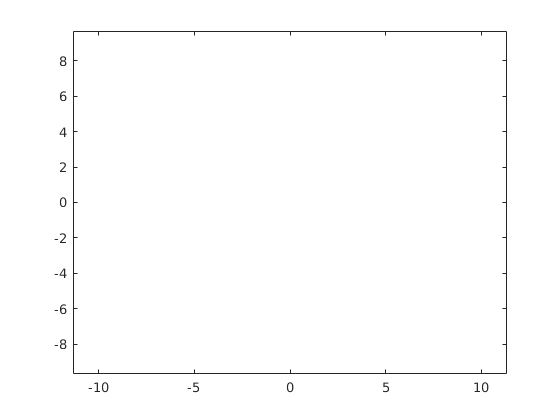

Ks = [1,2,3,4,5,7,10,15,20];
for(k=Ks)
    task1_6(sprintf('task1_5_c_%d.mat',k));
    input('hit')
end

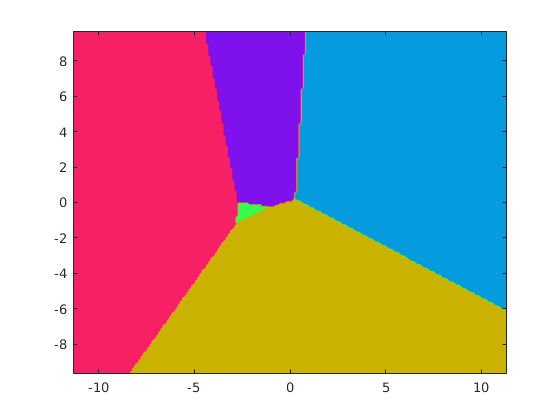

k=5;
Dmap = task1_7(sprintf('task1_5_c_%d.mat',k), 'task1_2_M.mat', 'task1_3_evecs.mat',...
    'task1_3_evals.mat', mean(Xtrn), 200);

save(sprintf('task1_7_dmap_%d.mat',k), 'Dmap');

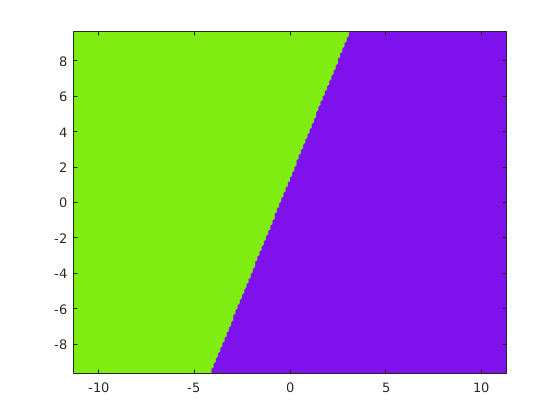

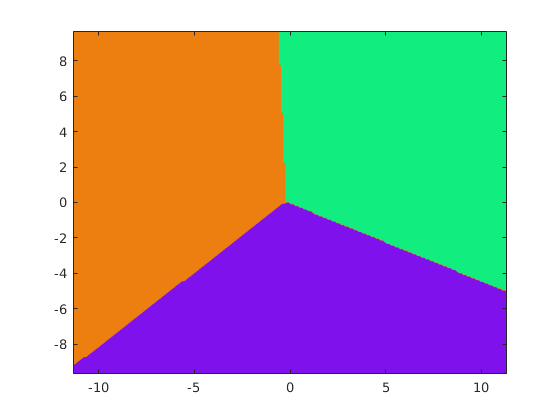

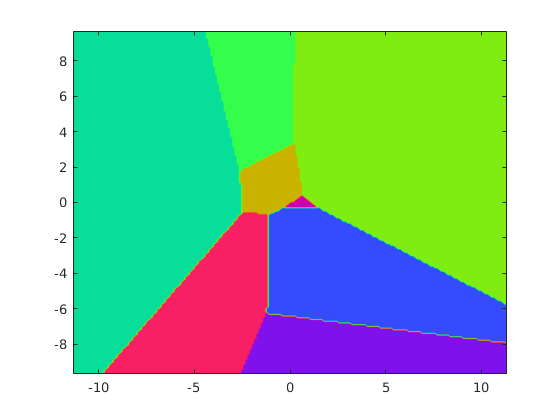

Ks = [1,2,3,5,10];
for(k=Ks)
    Dmap = task1_7(sprintf('task1_5_c_%d.mat',k), 'task1_2_M.mat', 'task1_3_evecs.mat',...
    'task1_3_evals.mat', mean(Xtrn), 200);
    save(sprintf('task1_7_dmap_%d.mat',k), 'Dmap');
end

Ks = [1,2,3,4,5,7,10];
for(k=Ks)
    task1_8(Xtrn(1:5000,:), Ytrn(1:5000,:), 50, k);
    input('hit')
end

[initSSE, finSSE, iterTimes] = task1_8(Xtrn(1:5000,:), 4, 500);
my_corr([initSSE iterTimes])

[initSSE, finSSE, iterTimes] = task1_8(Xtrn(1:8000,:), 5, 100, 'uni');

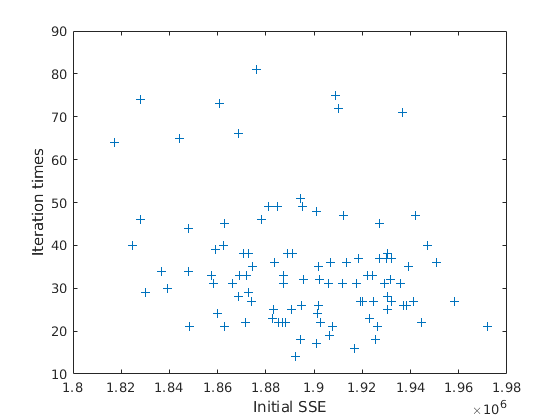

[initSSE, idx] = sort(initSSE, 'ascend');
plot(initSSE, iterTimes(idx,:),'+')
xlabel('Initial SSE');
ylabel('Iteration times');

mean(iterTimes)

ans = 35.0800

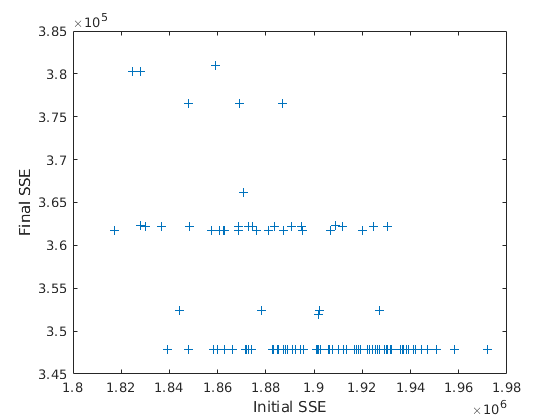

[initSSE, idx] = sort(initSSE, 'ascend');
plot(initSSE, finSSE(idx,:), '+')
xlabel('Initial SSE');
ylabel('Final SSE');

Ks = [1,3,5,10,20];
for(k=Ks)
    task2_1(Xtrn, Ytrn, Xtst, Ytst, [k]);
end

Elapsed time is 10.479334 seconds.


k = 1

N = 4014

Nerrs = 126

acc = 0.9686

Elapsed time is 10.552680 seconds.


k = 3

N = 4014

Nerrs = 138

acc = 0.9656

Elapsed time is 10.683611 seconds.


k = 5

N = 4014

Nerrs = 135

acc = 0.9664

Elapsed time is 10.885220 seconds.


k = 10

N = 4014

Nerrs = 144

acc = 0.9641

Elapsed time is 10.467985 seconds.


k = 20

N = 4014

Nerrs = 165

acc = 0.9589

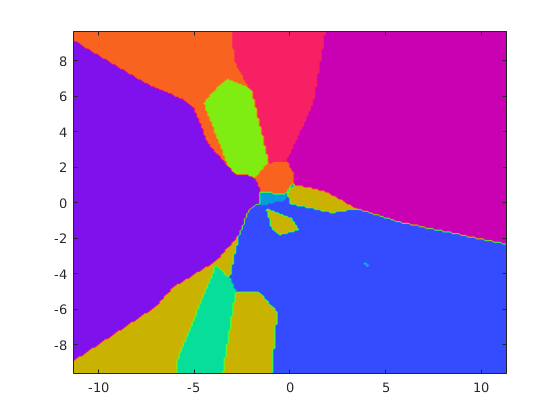

k=1;
N = 10000;
Xtrn2 = Xtrn(1:N,:); Ytrn2 = Ytrn(1:N,:);
Dmap = task2_2(Xtrn2, Ytrn2, k, 'task1_3_evecs.mat', 'task1_3_evals.mat', mean(Xtrn), 200);

save(sprintf('task2_2_dmap_%d.mat',k), 'Dmap');

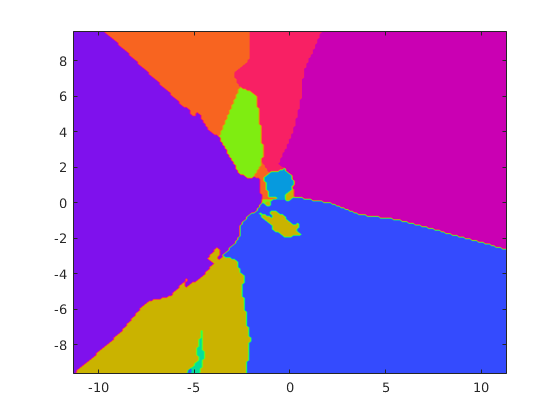

k=3;
N = 10000;
Xtrn2 = Xtrn(1:N,:); Ytrn2 = Ytrn(1:N,:);
Dmap = task2_2(Xtrn2, Ytrn2, k, 'task1_3_evecs.mat', 'task1_3_evals.mat', mean(Xtrn), 200);

save(sprintf('task2_2_dmap_%d.mat',k), 'Dmap');

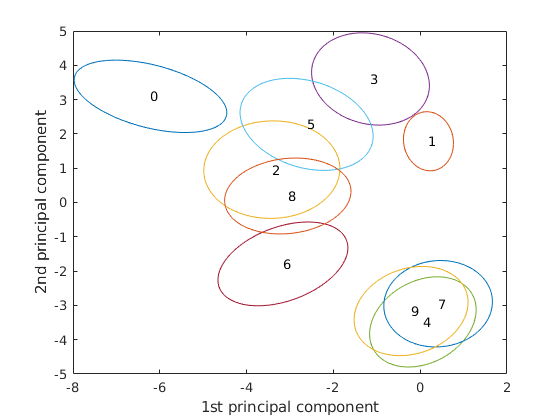

task2_3(Xtrn, Ytrn);

Corrs = task2_4(Xtrn, Ytrn);
save('task2_4_corrs.mat', 'Corrs');

task2_5(Xtrn, Ytrn, Xtst, Ytst, 0.01);

Elapsed time is 1.681425 seconds.


N = 4014

Nerrs = 220

acc = 0.9452

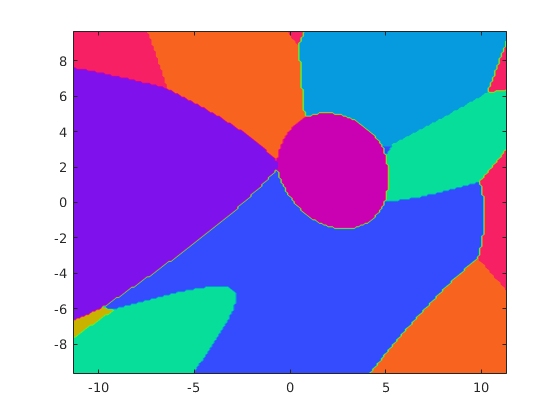

Dmap = task2_6(Xtrn, Ytrn, 0.01, 'task1_3_evecs.mat', 'task1_3_evals.mat',mean(Xtrn), 200);

save('task2_6_dmap.mat', 'Dmap');

ratio = [0.9, 0.8, 0.7, 0.6, 0.5, 0.4, 0.3];
for(r=ratio)
    [CM acc] = task2_7(Xtrn, Ytrn, Xtst, Ytst, 0.01, r);
    save(sprintf('task2_7_cm_%d.mat',r*100), 'CM');
    [r acc]
end

ans =     0.9000    0.9457


ans =     0.8000    0.9457


ans =     0.7000    0.9442


ans =     0.6000    0.9464


ans =     0.5000    0.9459


ans =     0.4000    0.9452


ans =     0.3000    0.9449


for(L=[2 5 10])
    task2_8(Xtrn, Ytrn, Xtst, Ytst, 0.01, L);
end

Elapsed time is 7.194039 seconds.


N = 4014

Nerrs = 183

acc = 0.9544

Elapsed time is 17.650556 seconds.


N = 4014

Nerrs = 144

acc = 0.9641

Elapsed time is 28.278832 seconds.


N = 4014

Nerrs = 105

acc = 0.9738